# CoP動揺分析　複数試行・複数被験者を一度に

※　Demo03 までは理解しておくこと

copSDAP = 3.9334

copSDML = 0.8986

copSDAP = 3.0240

copSDML = 1.1468

copSDAP = 8.7787

copSDML = 5.3447

copSDAP = 7.9623

copSDML = 2.9204

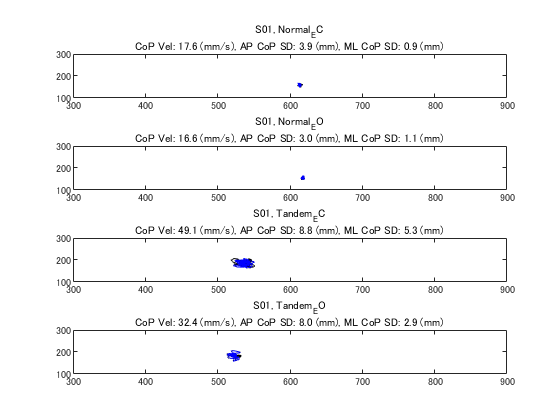

copSDAP = 10.4698

copSDML = 2.2967

copSDAP = 5.7008

copSDML = 2.0818

copSDAP = 13.2291

copSDML = 15.4792

copSDAP = 7.2842

copSDML = 17.6648

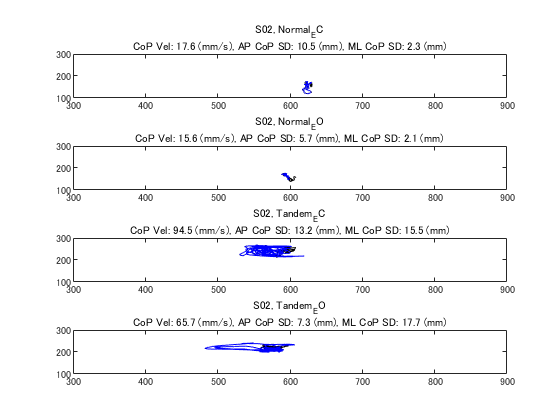

copSDAP = 3.3571

copSDML = 0.9999

copSDAP = 3.2933

copSDML = 0.9748

copSDAP = 9.5067

copSDML = 8.9797

copSDAP = 4.7937

copSDML = 4.1360

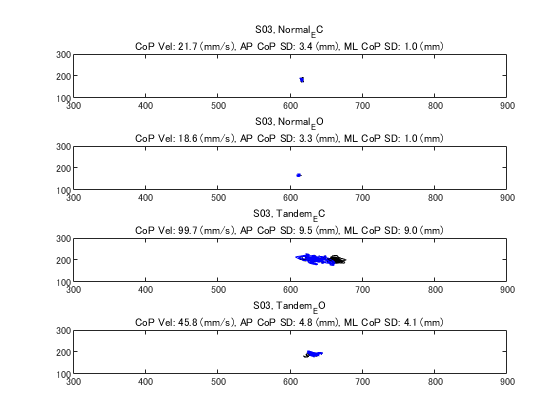

copSDAP = 2.4463

copSDML = 1.2555

copSDAP = 2.8426

copSDML = 1.2071

copSDAP = 9.3360

copSDML = 19.2981

copSDAP = 3.6775

copSDML = 3.2231

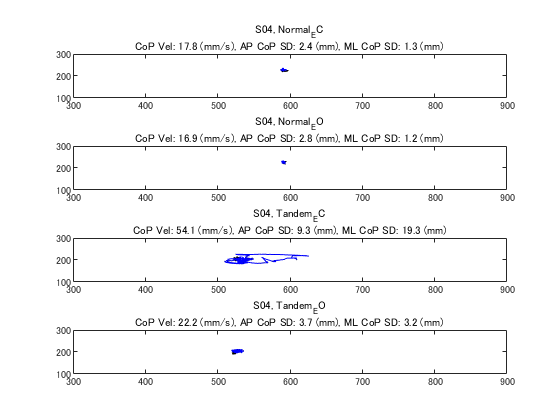

copSDAP = 2.9701

copSDML = 1.5884

copSDAP = 5.3872

copSDML = 2.5792

copSDAP = 7.7165

copSDML = 6.4715

copSDAP = 5.1700

copSDML = 3.0689

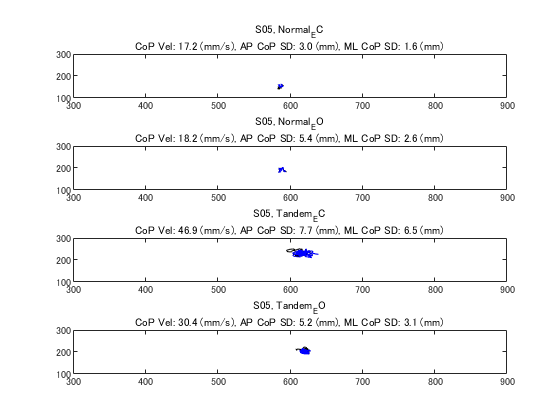

copSDAP = 3.8970

copSDML = 1.2631

copSDAP = 2.9356

copSDML = 0.7428

copSDAP = 9.8684

copSDML = 5.3100

copSDAP = 5.4860

copSDML = 4.0475

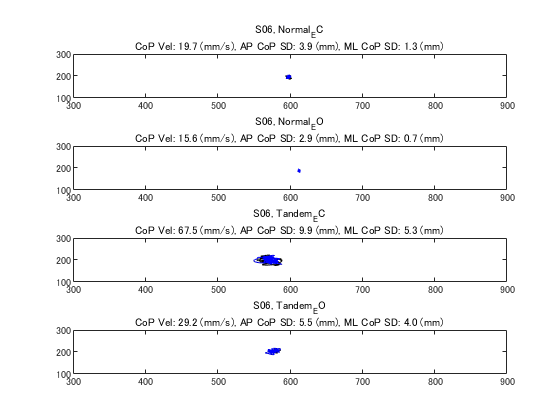

copSDAP = 4.8526

copSDML = 1.1424

copSDAP = 3.2775

copSDML = 1.2213

copSDAP = 12.4644

copSDML = 11.9638

copSDAP = 5.9035

copSDML = 3.8550

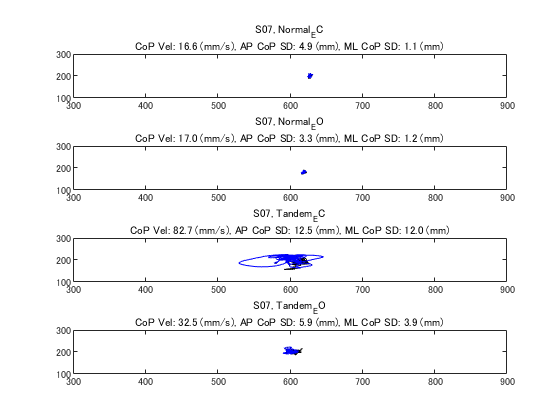

copSDAP = 4.4545

copSDML = 1.2566

copSDAP = 3.6791

copSDML = 1.1386

copSDAP = 9.1770

copSDML = 11.7137

copSDAP = 5.0354

copSDML = 5.0630

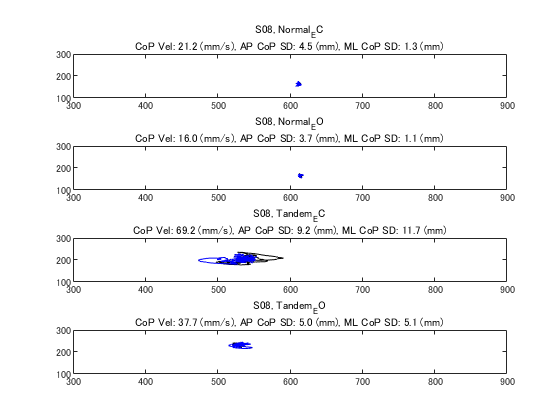

copSDAP = 2.2552

copSDML = 1.1954

copSDAP = 2.3692

copSDML = 1.1537

copSDAP = 7.2526

copSDML = 11.1376

copSDAP = 5.1974

copSDML = 3.3811

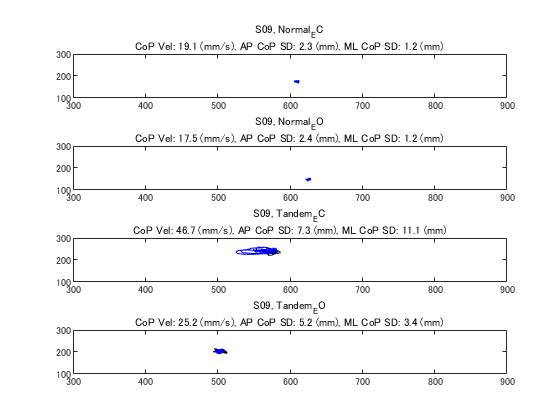

copSDAP = 3.6836

copSDML = 1.0787

copSDAP = 6.7652

copSDML = 1.2138

copSDAP = 8.5827

copSDML = 5.4327

copSDAP = 4.5185

copSDML = 4.4234

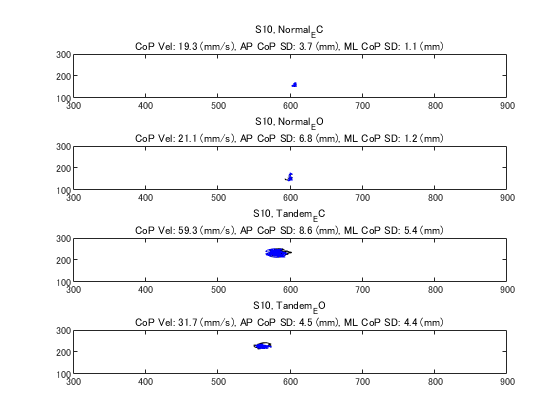

copSDAP = 2.5337

copSDML = 0.9783

copSDAP = 4.7104

copSDML = 1.0174

copSDAP = 9.9126

copSDML = 8.7501

copSDAP = 5.0375

copSDML = 4.6776

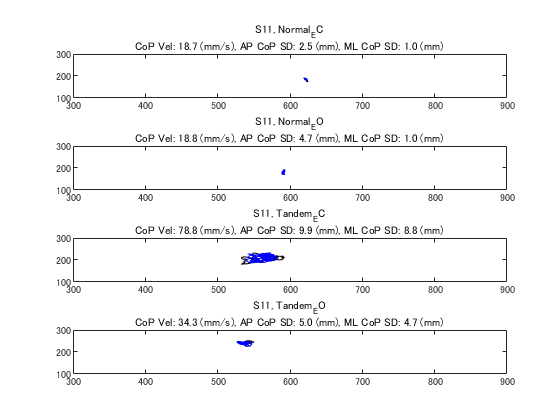

copSDAP = 3.9279

copSDML = 1.1554

copSDAP = 5.7518

copSDML = 2.5123

copSDAP = 10.9765

copSDML = 6.0777

copSDAP = 6.6419

copSDML = 3.3906

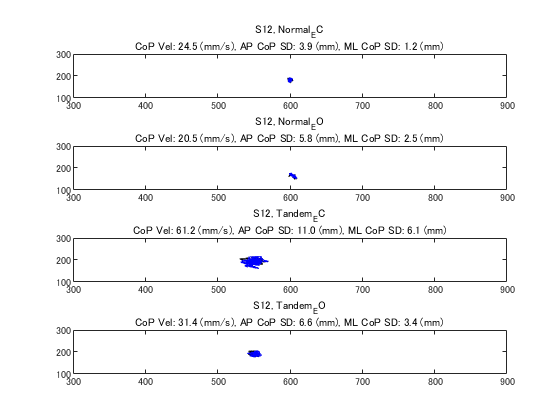

copSDAP = 2.4565

copSDML = 1.7034

copSDAP = 2.2443

copSDML = 1.3958

copSDAP = 9.2779

copSDML = 16.2660

copSDAP = 5.1042

copSDML = 7.8117

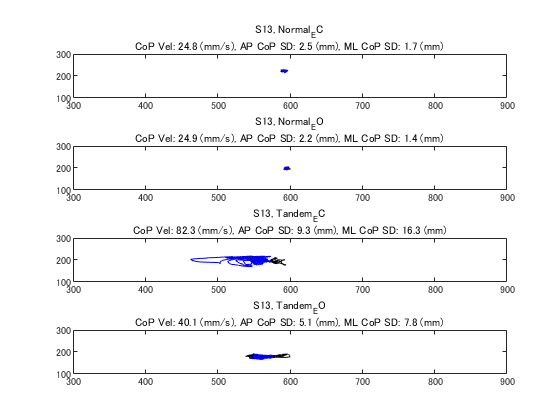

clear
close all
clc

% 分析する条件名（DataStruct内のフィールド名）
ConditionNameArray = {'Normal_EC', 'Normal_EO', 'Tandem_EC', 'Tandem_EO'} ;

% 分析区間を設定
% 静止立位のCoP動揺分析の場合、通常 20s 程度の区間を分析する
% "静止立位の定常状態"が保たれている区間を分析する必要がある
%
% 途中で姿勢が維持できなくなる等しているデータは、
% 除外するなど適切に取り扱う必要があるので細心の注意を払うこと
dur = 20000 ;
fStart = 2001 ;
fEnd = fStart + dur - 1 ; 


for iSubject = 1:13
    
    % *** 実験実習で測定計測したデータ を load***
    fileName = sprintf('StandData_S%02d', iSubject) ;
    load(fileName) ;
    
    figure(iSubject) ;
        
    
    for iCondition = 1:length(ConditionNameArray) 
        
        % cop データを抽出
        conditionName = ConditionNameArray{iCondition} ;
        cop = StandDataStruct.(conditionName).CoP ;
        copX = cop(:,1) ;
        copY = cop(:,2) ;
        
        % // CoP　指標の分析。右辺に適切な分析コードを書くこと //
        % CoP velocity: 単位時間あたりのCoP軌跡長 (mm/s)
        copDis = sum(diff(cop).^2,2).^0.5;
        copVel = sum(copDis(fStart:fEnd-1)) / (dur/1000) ;
        
        % CoP SD
        copSDAP = std(copY(fStart:fEnd))
        copSDML = std(copX(fStart:fEnd))
        
        % ////

        % 必ずプロットを確認して、異常がないか確認すること
        subplot(4,1,iCondition) ;
        plot(copX, copY, 'k') ; hold on
        plot(copX(fStart:fEnd), copY(fStart:fEnd), 'b')
        
        set(gca, 'xlim', [300,900], 'ylim', [100, 300])
        title({[sprintf('S%02d, ', iSubject), conditionName];...
               sprintf('CoP Vel: %0.1f (mm/s), AP CoP SD: %0.1f (mm), ML CoP SD: %0.1f (mm)', copVel, copSDAP, copSDML)})
        
        % figure を保存
        filePath = sprintf('Demo12_CoPFigures/CoPFig_S%02d', iSubject) ;
        saveas(gcf, filePath, 'png')
        
        %　エキスポート用の構造体とテーブル
        S(iSubject).(['CopVel_', conditionName]) = copVel ;
        S(iSubject).(['APCoPSD_', conditionName]) = copSDAP ;
        S(iSubject).(['MLCoPSD_', conditionName]) = copSDML ;
        
    end
end

### 注意事項：　NormalとTandemでCoPの左右・前後方向が異なる

Demo11でも述べたが、Tandem条件では、copYが左右方向、copXが前後方向となることに注意する。なので、copSDAPとcopSDMLの扱いには**十分注意すること**。

ex.) Normalの左右方向のCoP標準偏差はcopSDML、Tandemの左右方向のCoP標準偏差はcopSDAP

なお、Demo12で算出されるNormalとTandemのCoPプロットは、それぞれ白矢印の方向から見ること。

（Normal：　上図、Tandem：　下図）

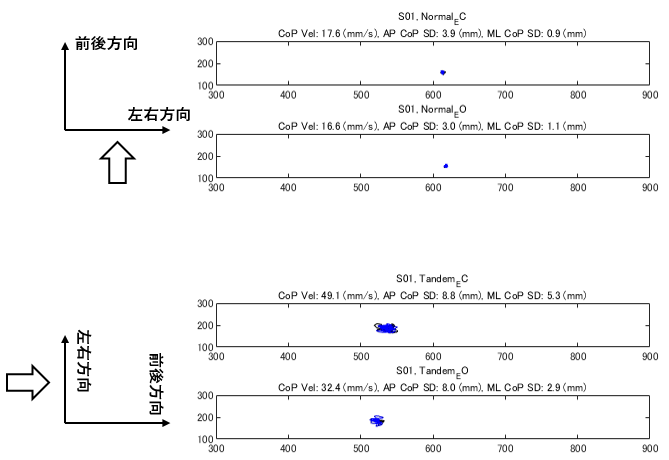

## エキスポート用の構造体とテーブル

array editor から、テーブルの数値をコピーして Excel 等に貼り付けてもよいし、writetable関数を用いて、テーブルをcsvファイルに保存してもよい。

統計検定を行う前に、プロットを確認して、分析された数値が正しいものであるか、必ず確認すること


T = struct2table(S)

T = 13×12 table
    CopVel_Normal_EC    APCoPSD_Normal_EC    MLCoPSD_Normal_EC    CopVel_Normal_EO    APCoPSD_Normal_EO    MLCoPSD_Normal_EO    CopVel_Tandem_EC    APCoPSD_Tandem_EC    MLCoPSD_Tandem_EC    CopVel_Tandem_EO    APCoPSD_Tandem_EO    MLCoPSD_Tandem_EO
    ________________    _________________    _________________    ________________    _________________    _________________    ________________    _________________    _________________    ________________    _________________    _________________

         17.625              3.9334               0.89856              16.588               3.024                1.1468              49.146              8.7787               5.3447               32.385              7.9623               2.9204      
          17.57               10.47                2.2967               15.58              5.7008                2.0818              94.476              13.229               15.479                65.72              7.2842               